## These lines of code are used to compile data     needed for deriving a conditional GMM

clc; clear; close all;

addpath('G:\Berkeley_RVT_Study_2020_2021\RVT_Papers\Bayless2018_check');

addpath('G:\Berkeley_RVT_Study_2020_2021\RVT_Papers\dataout');

addpath('G:\Berkeley_RVT_Study_2020_2021\RVT_Papers\NGA_West2_database');

load('Extra_EAS_NGA_West2_for_RVT.mat');  % this data is new.

dur = readtable('NGA_West2_GM_Duration_5_80.xlsx');


% Match between two data set. 

[C, ia, ib] = intersect(dur.RSN, df.RecordSequenceNumber);

RSN_match = [dur.RSN(ia) df.RecordSequenceNumber(ib)];

D = dur.GM_D580(ia);

df = df(ib,:);

df = addvars(df, D,'before','RecordSequenceNumber');

% %%%%%%%%%%%%%%%%%%% pulse records % % 
addpath('D:\UC_Berkeley_study\Conditional_GMMs_2020');

%%%%%%%%%%% This data relevant to those used in the BA19 %%%%%%%%%%%%

% addpath('G:\Gaussian Process & RVT Study\RVT_Papers\Extrap_EAS_data');
% load('df_used_by_ba19_ngaw2_extension.mat');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% df = df(df.EarthquakeMagnitude>3.0 & df.ClstD_km_<30,:);

% % % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

 VarNames = df.Properties.VariableNames;
 
 f_eas_hz_loc = VarNames(contains(VarNames,' Hz'));
 
 f_eas_hz = split(f_eas_hz_loc); 
 
 f_eas_hz = str2double(f_eas_hz(:,:,1));
 
% Consider the usable frequency range
 eas_array_flatfile = df(:, f_eas_hz_loc); % eas amplitude 301 values. 

% this is data array of useable eas amplitude. 
 eas_array_useable = table2array(eas_array_flatfile);
    
% 24 periods for the interest of intensity measures
 y_gmims = {'T0_010S','T0_020S','T0_030S','T0_040S','T0_050S','T0_075S',...
              'T0_100S','T0_120S','T0_150S','T0_170S', ...
                 'T0_200S','T0_250S','T0_300S','T0_400S','T0_500S','T0_750S', ...
                           'T1_000S','T1_500S','T2_000S','T3_000S','T4_000S','T5_000S','T7_500S','T10_000S'};
 
 period = [0.01 0.02 0.03  0.04 0.05  0.075  0.1  0.12  0.15  0.17  0.2  0.25 0.30 0.4  0.5 ...
            0.75  1.0   1.5   2  3  4  5  7.5  10];
     
% Create data frame to store the output of 24 period.
 m0_ = nan(length(df.EarthquakeMagnitude),length(period)); 

 mrio_ = nan(length(df.EarthquakeMagnitude),length(period));  

 pSa_= nan(length(df.EarthquakeMagnitude),length(period));
  
for Tn = period
% pseudo spectral acceleration 
       ip = find(period == Tn); Tn
       tempt = df.(char(y_gmims(period==Tn)));
%  multiply EAS with Transfer function: EAS*TF(fosc).
       [~, IRw] = SDOFImpRespFreqD(f_eas_hz,Tn,0.05);
     
       EAS_SDOF = eas_array_useable.*IRw;
% Compute Zero moment of ESA spectrum according to Eq. 3
       
   for k = 1:length(df.EarthquakeMagnitude)
       
       xf = EAS_SDOF(k,:);
       
       M = df.EarthquakeMagnitude(k);
       
       Rrup = df.ClstD_km_(k);
       
       [eas_m0,  eas_mr] = Estimate_RVT_param(Tn, f_eas_hz, xf, M, Rrup);
        
        
       if tempt(k)>0
            pSa_(k,ip) = tempt(k);
            m0_(k,ip) = eas_m0;    
            mrio_(k,ip) = eas_mr;
       end
           
   end
end

Tn = 0.0100

Tn = 0.0200

Tn = 0.0300

Tn = 0.0400

Tn = 0.0500

Tn = 0.0750

Tn = 0.1000

Tn = 0.1200

Tn = 0.1500

Tn = 0.1700

Tn = 0.2000

Tn = 0.2500

Tn = 0.3000

Tn = 0.4000

Tn = 0.5000

Tn = 0.7500

Tn = 1

Tn = 1.5000

Tn = 2

Tn = 3

Tn = 4

Tn = 5

Tn = 7.5000

Tn = 10


dfL = df(:,{'RecordSequenceNumber','EQID','StationSequenceNumber','EarthquakeMagnitude','ClstD_km_','Vs30_m_s_SelectedForAnalysis'});

dfL2 = df(:,{'D','DepthToTopOfFaultRuptureModel','HP_H1_Hz_','HP_H2_Hz_','LP_H1_Hz_','LP_H2_Hz_'});

dpSa = array2table(pSa_);

dmo = array2table(m0_);

dm2 = array2table(mrio_);

% create data frame for moment 
df_ = [dfL dfL2 dpSa dmo dm2];
% remove negative value of pSa
df_ = rmmissing(df_);

% save('dfactmoment.mat','dfact');

## Mixed Effect Regression Model

   ck_array = [];
   
   
   sig = []; 
   
   plt = 'n';
   
   ck0_array = [];
   
 
 for tn = period  
    
        ip = find(period == tn);
        
        % Consider usable freq 
        ifc = 1.25*max(df_.HP_H1_Hz_,df_.HP_H2_Hz_) <= 1/tn;
        
        df_tn = df_(ifc,:);
        
        pSa_tn = df_tn.(['pSa_',num2str(find(period==tn))]); 
        
        m0 = df_tn.(['m0_',num2str(find(period==tn))]);
        
        mrio = df_tn.(['mrio_',num2str(find(period==tn))]);
         
        assert(all(pSa_tn>0),'All individual must be greater than 0');
        
        assert(all(m0>0),'All individual must be greater than 0');
        
        % Prediction from the conditional Model
        mag = df_tn.EarthquakeMagnitude;
        
        rrup = df_tn.ClstD_km_;
        
        d80 = df_tn.D;
        
        ix = mag>=6.5 & rrup <= 15;
        

        y = nan(length(mag),1);
        
        fc1a = nan(length(mag),1); 
        
        fc1b = nan(length(mag),1); 
        
    for k = 1:length(mag)
        [y(k,1), fc1a(k,1), fc1b(k,1)] = Conditional_GMM_PA20_new3(tn, m0(k), mrio(k), mag(k), rrup(k), d80(k),'xxx');
    end

            
            xRes = log(pSa_tn) - log(y);  
       %%%%%%%%%% Mixed effect Regression %%%%%%%%%%%%%%
    
            fm1 = mag-5.5;
            
            fgeo = log(rrup + 5*exp(0.4*(mag-6.0)));
            
            tb = table(xRes,fgeo, fc1a, fc1b, df_tn.EQID,...
                            'VariableNames',{'xRes','fgeo','fc1a','fc1b','EQID'});

            lme = fitlme(tb,'xRes ~ 1 + (1|EQID)'); 
            
            
            ck = fixedEffects(lme);
            dBe = randomEffects(lme);
            Wes = residuals(lme);
            dBe = dBe + ck(1);
              

            % %  M>6.5 & R<15   
            [~, ia] = unique(df_tn.EQID);  Mia = mag(ia);
            
            ck_array = [ck_array [ck; mean(dBe(Mia>=6.5)); mean(Wes(ix));  mean(dBe(Mia>=6.5))+mean(Wes(ix))]]; 
 
    if strcmp(plt,'y') 
        
            [~, ia] = unique(df_tn.EQID);
            
            fig = figure;
            subplot(2,1,1)
            plot(mag(ia),dBe + ck(1),'ko','MarkerFaceColor',"b"); hold on;
            z2=plot([3.5 8],[ck(1) ck(1)],'r-','LineWidth',2);
            % legend(z2,{['c_L=',num2str(round(ck(1),3))]})
            axis([3.5 8 -1 1]); grid on;
            xlabel('M');ylabel('dBe');
            set(gca,'ytick',-1:0.5:1);
            h = gca;
            h.YAxis.MinorTick = 'on'; % 
            h.YAxis.MinorTickValues = -1:0.2:1; 
            title(['tn',num2str(tn),'s',' - \sigma_T=',num2str(std(xRes))]);
           
%             subplot(2,3,find(prd==tn));
%             figure('Position',[50 50 500 320]);

            subplot(2,1,2)
            t1=semilogx(rrup,Wes,'ko','MarkerFaceColor','b'); hold on;
            t2=semilogx(rrup(ix),Wes(ix),'ko','MarkerFaceColor','r'); hold on;
           
            semilogx([0.01 500],[mean(Wes(ix)) mean(Wes(ix))],'r-','LineWidth',2); hold on;
            
            h = gca;
            h.YAxis.MinorTick = 'on'; % 
            h.YAxis.MinorTickValues = -1:0.2:1; 
            set(gca,'ytick',-1:0.5:1);
            axis([0.1 500 -1 1]); 
            title(['c=',num2str(round(mean(Wes(ix)),3))]);
            grid on; xlabel('R_{rup}, [km]');ylabel('\delta W_{es}');
            legend([t1;t2],'alls','near fault records');
%             saveas(fig,['figures\fig.',num2str(tn),'.tiff']);
    end            

            % ck0_array = [ck0_array [ck(1); mean(Wes(ix))]]; 

  end
      
  

## Smooth Coefs

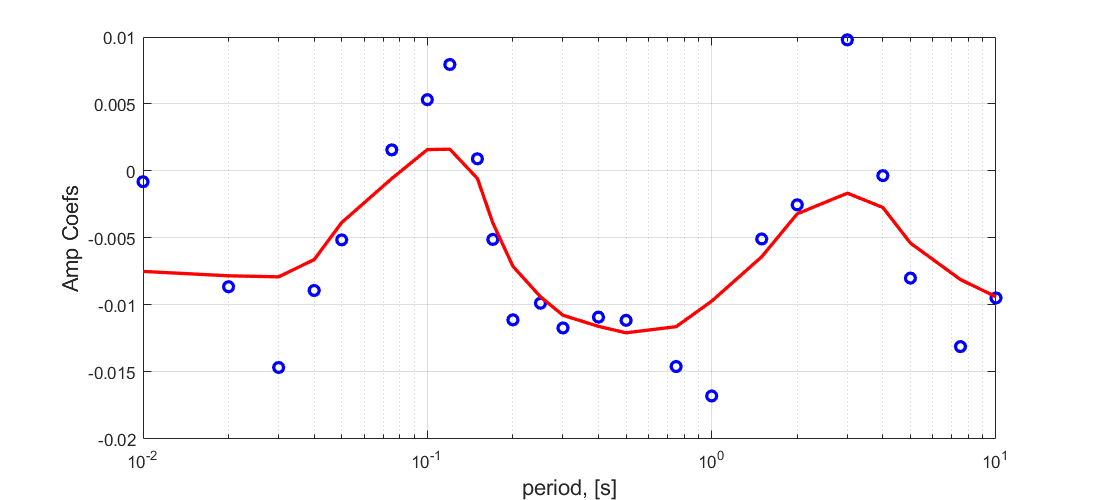

addpath('G:\Berkeley_RVT_Study_2020_2021\RVT_Papers\lib\smoothing');
 
x = ck_array(2,:);

SmoothY = fastsmooth(x,3,4,1);

figure('Position',[50 50 880 400]);
semilogx(period,x,'bo','LineWidth',2); hold on;
semilogx(period,SmoothY,'r','LineWidth',2); hold on;
% legend('raw','smoothed'); set(gca,'fontsize',12);
xlabel('period, [s]','FontSize',13); %  ylabel('\mu','FontSize',16);
grid on; ylabel('Amp Coefs','FontSize',13);

% axis([0.01 10 -0.1 0.1]);

## Check for Residuals

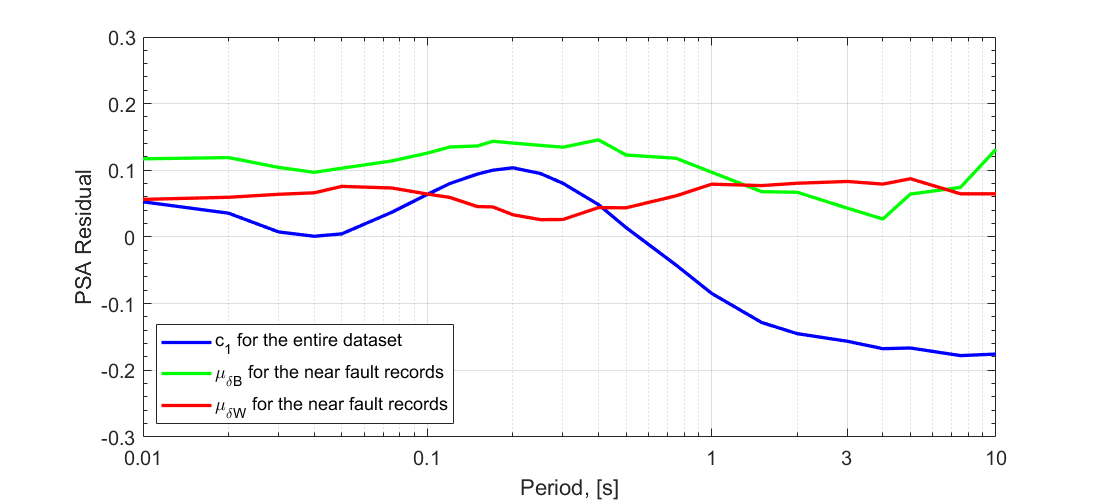

mu_e_rvt = [0.0528	0.0357	0.0076	0.0011	0.0047	0.0371	0.0639	0.0802	0.0944	0.1002	0.1038	0.0952	0.0805	0.0486	0.0141	-0.0422	-0.0846	-0.1283	-0.1450	-0.1564	-0.1675	-0.1665	-0.1779	-0.1756];
% mu_w_rvt = [0.1053	0.1059	0.0992	0.0941	0.1025	0.1144	0.1257	0.1328	0.1298	0.1391	0.1358	0.1327	0.1317	0.1356	0.1247	0.1128	0.0980	0.0583	0.0511	0.0334	0.0270	0.0662	0.0737	0.1201];
% mu_wp_rvt = [0.1576	0.1579	0.1519	0.1410	0.1484	0.1585	0.1796	0.1702	0.1824	0.1873	0.1820	0.1857	0.1692	0.1672	0.1739	0.1715	0.1537	0.1119	0.1136	0.0793	0.0622	0.1111	0.0850	0.1624];
% mu_e_rvt = [0.0529	0.0358	0.0077	0.0012	0.0048	0.0372	0.0640	0.0802	0.0944	0.1003	0.1039	0.0953	0.0806	0.0487	0.0141	-0.0422	-0.0846	-0.1284	-0.1451	-0.1564	-0.1675	-0.1665	-0.1779	-0.1757];
mu_e_rvtM65 = [0.1173	0.1191	0.1044	0.0970	0.1032	0.1141	0.1258	0.1350	0.1366	0.1436	0.1409	0.1374	0.1347	0.1457	0.1230	0.1181	0.0971	0.0680	0.0671	0.0433	0.0270	0.0644	0.0744	0.1316];
mu_w_rvtM65 = [0.05641	0.05959	0.06406	0.06629	0.07593	0.07350	0.06445	0.05938	0.04567	0.04512	0.03336	0.02599	0.02627	0.04408	0.04379	0.06178	0.07925	0.07712	0.08064	0.08332	0.07934	0.08743	0.06478	0.06478];

 figure('Position',[50 50 880 400]);
 semilogx(period,mu_e_rvt,'b-','LineWidth',2); hold on;
 semilogx(period,mu_e_rvtM65,'g-','LineWidth',2); hold on;
 semilogx(period,mu_w_rvtM65,'r-','LineWidth',2); hold on;

%  semilogx(period,ck_array(1,:),'b-','LineWidth',2); hold on;
%  semilogx(period,ck_array(2,:),'r-','LineWidth',2); hold on;

 legend('c_1 for the entire dataset','\mu_{\deltaB} for the near fault records',...
         '\mu_{\deltaW} for the near fault records',...
         'location','southwest');
 xlabel('Period, [s]','FontSize',12); 
 ylabel('PSA Residual','FontSize',12);
 grid on; axis([0.01 10 -0.3 0.3]);
 set(gca,'Ytick',-0.5:0.1:0.5);
 set(gca,'FontSize',12);
 set(gca,'YMinorTick','on');
 set(gca,'Xtick',[0.01,0.1,1,3,10]);

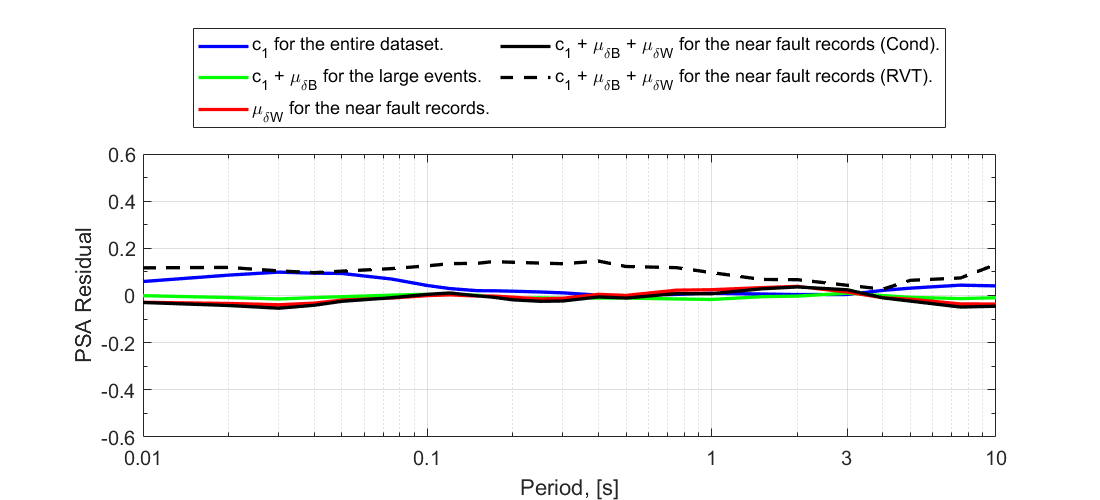

 
 %%%%% %%%%%%%%%%% fig10 %%%%%%%%%%%%%%%%%%%%%%%%%
 figure('Position',[50 50 880 400]);
 semilogx(period,ck_array(1,:),'b-','LineWidth',2); hold on;
  semilogx(period,ck_array(2,:),'g-','LineWidth',2); hold on;
   semilogx(period,ck_array(3,:),'r-','LineWidth',2); hold on;
   semilogx(period,ck_array(4,:),'k-','LineWidth',2); hold on;
    semilogx(period,mu_e_rvtM65,'k--','LineWidth',2); hold on;
  legend('c_1 for the entire dataset.','c_1 + \mu_{\deltaB} for the large events.',...
         '\mu_{\deltaW} for the near fault records.','c_1 + \mu_{\deltaB} + \mu_{\deltaW} for the near fault records (Cond).',...
         'c_1 + \mu_{\deltaB} + \mu_{\deltaW} for the near fault records (RVT).','location','northoutside','NumColumns',2);

 xlabel('Period, [s]','FontSize',12); 
 ylabel('PSA Residual','FontSize',12);
 grid on; axis([0.01 10 -0.6 0.6]);
 set(gca,'Ytick',-0.6:0.2:0.6);
 set(gca,'FontSize',12);
 set(gca,'YMinorTick','on');
 set(gca,'Xtick',[0.01,0.1,1,3,10]);
 
    h = gca;
    h.YAxis.MinorTick = 'on';
    h.YAxis.MinorTickValues = -1:0.1:1;   

## SDOF function

function [Hw, IR] = SDOFImpRespFreqD(EAS_Freq,Tn,beta)
% define the properties of system
         fn = 1/Tn;
         f = EAS_Freq;
         Hw = -fn.^2./((f.^2-fn.^2) - 1i*2*f*fn*beta);
         IR = abs(Hw); 
end

## Estimate RVT parameters

function [eas_m0, input2] = Estimate_RVT_param(Tn, f_eas_hz, xf, M, Rrup)
         eas_m0 = 2*trapz(f_eas_hz,(2*pi*f_eas_hz).^0.*xf.^2);
         eas_m1 = 2*trapz(f_eas_hz,(2*pi*f_eas_hz).^1.*xf.^2);
         eas_m2 = 2*trapz(f_eas_hz,(2*pi*f_eas_hz).^2.*xf.^2);
         %input2 = sqrt(eas_m2^2/(eas_m0*eas_m4));
         input2 = sqrt(eas_m2/eas_m1);
end

## Magnitude Function Form

% function fmag_1 = f_mag(c,xdata)
%        % Assign variables
%        input = xdata(:,1);
%        M = xdata(:,2);
%        
%        a1 = c(1);
%        a2 = c(2);
%        a3 = c(3);
%        
%         fmag_1input = zeros(length(M),1);
%         for i = 1:length(M)
%             if M(i)<5.5
%                 fmag_1input(i,1) = a2*log(input(i)); 
%             elseif M(i)<=7.0
%                 fmag_1input(i,1) = (a2+ (a3-a2)*(M(i)-5.5)/1.5)*log(input(i));
%             else
%                 fmag_1input(i,1) = a3*log(input(i));
%             end
%         end
%         fmag_1 = a1 + fmag_1input;
%         
% end